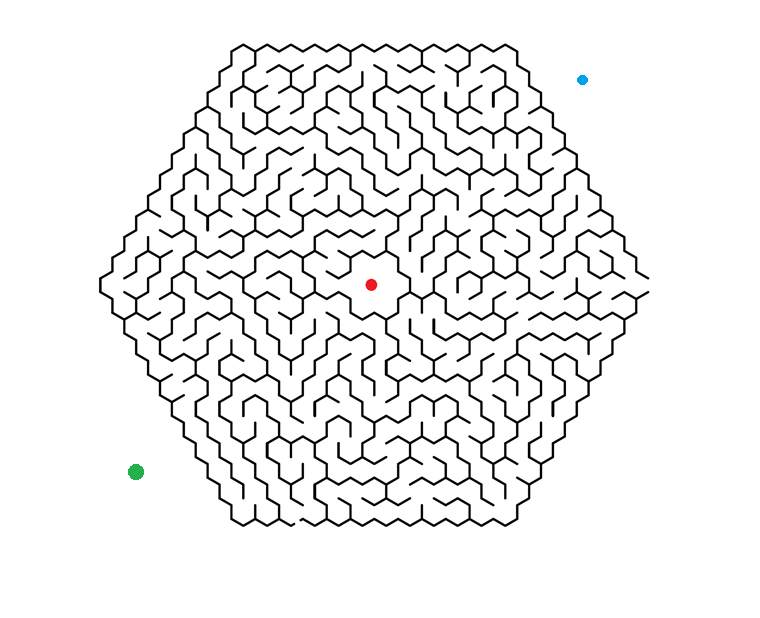

I = imread('Laberint.png');

imshow(I);

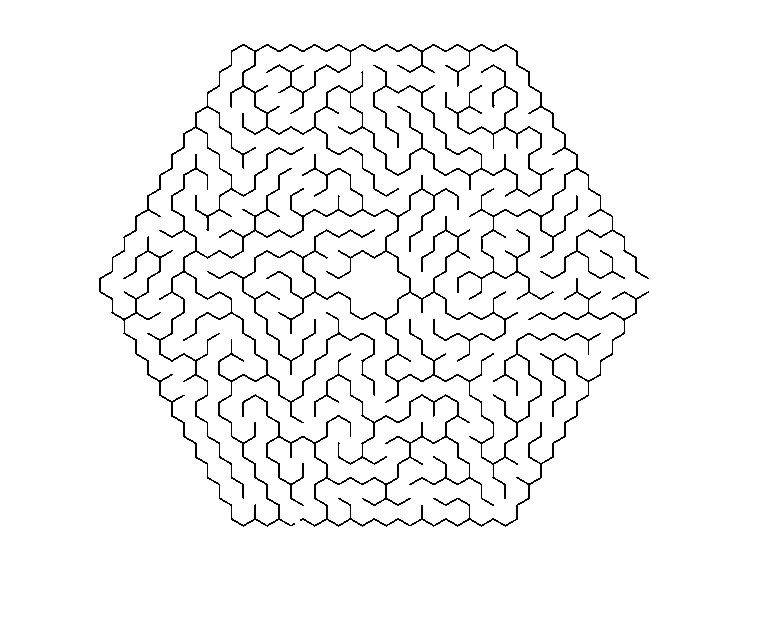



G = rgb2gray(I);
SE = [1,1,1;1,1,1;1,1,1];

%punt inicial verd
ini = I(:,:,2)>100 & I(:,:,1)<100 & I(:,:,3)<100;

%punt inicial blau
ini = I(:,:,2)<200 & I(:,:,1)<50 & I(:,:,3)>100;

%punt final vermell
fin =  I(:,:,1)>100 & I(:,:,2)<100 & I(:,:,3)<100;


%imatge condicio (laberint)
lab = G>50;
imshow(lab);

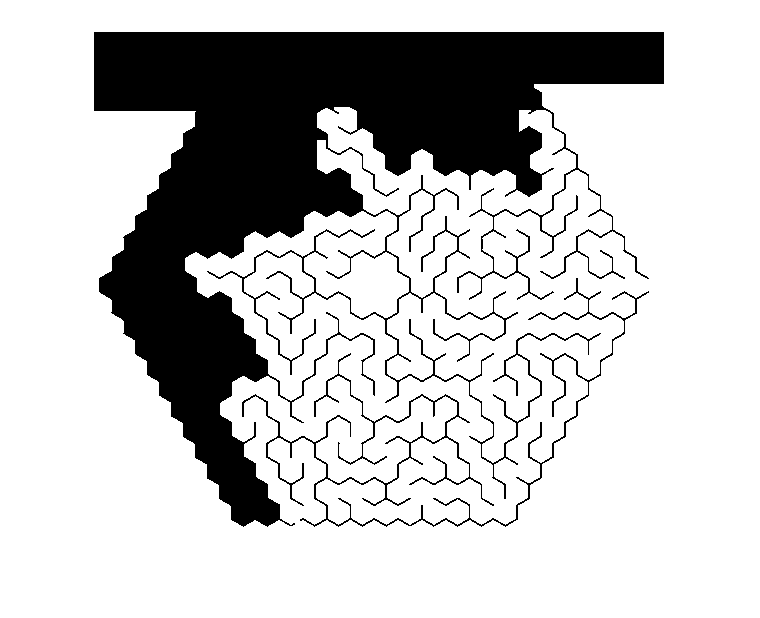


F = ini;
pixels = 1;

dist = im2double(ini);


while sum(sum(F&fin))==0
    pixels = pixels+1;
    abans = F;
    F = imdilate(F,SE);
    F = F&lab;
    pintats = F-abans;
    dist = dist + pintats*pixels;
end

%PART NOVA CANVIANT INI I FIN
ini2 = fin;
fin2 = ini;

F2 = ini2;

pixels2 = 1;

dist2 = im2double(ini2);

while sum(sum(F2&fin2))==0
    pixels2 = pixels2+1;
    abans2 = F2;
    F2 = imdilate(F2,SE);
    F2 = F2&lab;
    pintats2 = F2-abans2;
    dist2 = dist2 + pintats2*pixels2;
end

imshow(dist2);

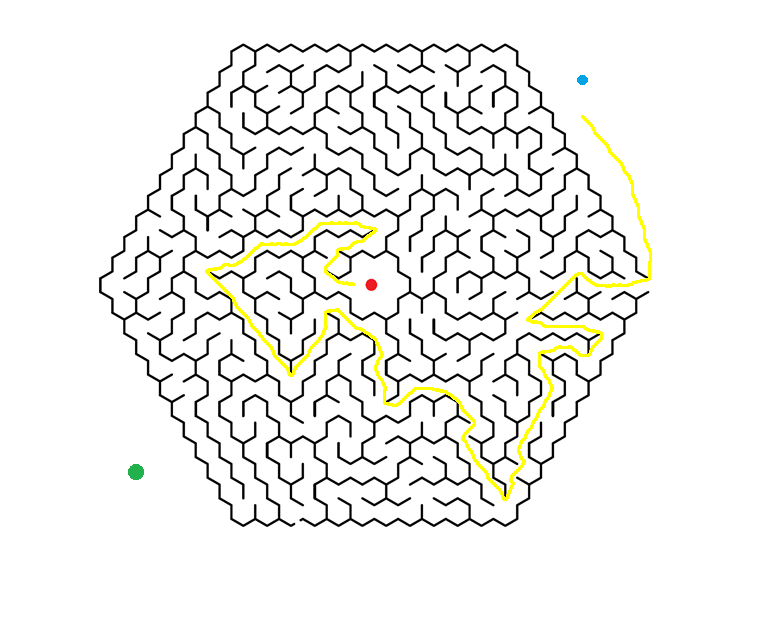


distTOT = dist+dist2;
distTOT = distTOT==pixels+1;

distTOT = bwskel(distTOT);
distTOT = imdilate(distTOT,SE);
FINAL = imoverlay(I,distTOT,'yellow');

%dilate dilata el blanc
imshow(FINAL);